% This script reproduces simulations from Pogodaev et al., 2020
% Analysis of Resilience in an Oscillating Enzymatic Reaction Network Reveals the Influence of Timing and Amplitude of Perturbations

% The model of the trypsin oscillator is based on the previous work
% published in Wong et al. JACS 2017, Pogodaev et al. JACS 2017.
% https://doi.org/10.1021/jacs.7b00632, https://doi.org/10.1021/jacs.7b08109

% The whole script takes ~40 sec to run on a normal office computer (Intel i7-6700, 8Gb RAM,
% Windows 7, Matlab 2020a). 
% By default, the heat map from Figure 3 is plotted based on saved data. 
% One can change CalculateHeatMap=false to ...=true to turn on the calculation.
% The calculation of the heatmap takes about 30 min.

% In the end of the script several functions are written
% function [f] = ODE_TrypsinOsc(...) - Provides a set of ordinary
% differential equaitons
% function [t,y]=OscIntegration(...) - Integrates the ODEs and return time
% traces
% [NumberCycles, TrMax_LC]=FindLC(...) - calculates the number of cycles to
% reach the limit cycle
% [x_proj,y_proj]=Projection(...) - performs an orthographic projection of
% 3D limit cycle to a 2D limit cycle
 
% To reproduce colours of the heat map (Figure 3) one has to download
% brewermap.m from
% https://nl.mathworks.com/matlabcentral/fileexchange/45208-colorbrewer-attractive-and-distinctive-colormaps.
% Otherwise the standard MATALB colormap is used.

% Have a nice day!
%     (  )   (   )  )
%      ) (   )  (  (
%      ( )  (    ) )
%      _____________
%     <_____________> ___
%     |             |/ _ \
%     |               | | |
%     |               |_| |
%  ___|             |\___/
% /    \___________/    \
% \_____________________/

%Standard conditions for all figures
PhotoInh0=20*0.01;
Time0=50;
IrrDuration0=0.08;
volume=118 %Volume of the flow reactor, µL

volume = 118

flowrate=44 % Total flow rate, µL/h

flowrate = 44


R_1=1; % Full model, all reactions are included
Tg0=0.1667 %mM

Tg0 = 0.1667

Tr0=0.000215 %mM

Tr0 = 2.1500e-04

ProI0=1.2 %mM

ProI0 = 1.2000

Ap0=31 % u/mL

Ap0 = 31


% Specification of the used colors. Some colors are based on colormaps
% created by Cynthia Brewer https://colorbrewer2.org/
Color_LC=[221,28,119]/255;
Color_Osc=[82,82, 82]/255;
Color_Tops=[178,24,43]/255;
Color_OscGrey=[153,153,153 ]/255;
Color_Orange=[255 87 31 ]/255;
Color_InhGrey=[244,165,130]/255;
Color_Inh=[202,0,32]/255;

## Figure 2. Simulation of a low resilience oscillator.

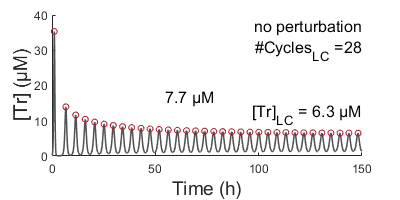

%Parameters different from the default parameters
PhotoInh=0; % No Photo-Inh
Time=300;
IrrTimeStart=20; % Irradiation time is provided,
IrrDuration=0.16;

%Integration for the default conditions
[t,y]=OscIntegration(volume,flowrate, R_1,Tg0,Tr0,ProI0,Ap0, PhotoInh,Time,  IrrTimeStart, IrrDuration);
Tr=y(:,2)*1000;
[pks,locs] = findpeaks(Tr,'MinPeakHeight',1);

NumberCycles=FindLC(Tr, 0.3,[]);

figure
width=400;
height=200;
set(gcf,'position',[0,0,width,height])


hold on
plot(t,Tr,'LineWidth',1, 'Color', Color_Osc); % plot Tr vs time
scatter(t(locs),pks,20, Color_Tops,'LineWidth',0.5) % circle to higlight tops of the peaks

%Formatiing of the figure
xlabel('Time (h)','FontSize',14);
ylabel('[Tr] (µM)','FontSize',14);
xlim([0 150])
ax=gca;
text(t(locs(11))*1.15, pks(11)*1.8,[ num2str(pks(11),'%.1f') ' µM'],'Units','data','HorizontalAlignment','left','VerticalAlignment','bottom','FontSize',12);
text(ax.XLim(2), ax.YLim(2), ['no perturbation' newline '#Cycles_L_C =' num2str(NumberCycles,'%.0f')],'Units','data','HorizontalAlignment','right','VerticalAlignment','top','FontSize',12);
text(ax.XLim(2), pks(end)*1.25,['[Tr]_L_C = ' num2str(pks(end),'%.1f') ' µM'],'Units','data','HorizontalAlignment','right','VerticalAlignment','bottom','FontSize',12);
hold off

## Saved data for the heatmap to save the computation time.

SavedDeltaCycles=[0,-1,-1,-1,0,0,-1,0,0,-1,-1,-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,0,-1,0,0,0,0,0,-1,-1,-1,-1,0,0,0,0,0,0,0,0,0,0,0,0,-1,-1,-1,-1,-1,0,0,0,0,0,1,1,1,1,
1,0,0,1,1,1,1,0,0,0,1,0,0,0,1,0,1,0,0,0,0,0,0,0,0,0,1,1,0,1,0,1,1,1,2,2,2,1,1,1,1,1,2,2,1,1,1,1,1,0,0,0,0,0,1,1,1,1,1,1,1,
0,-1,-1,-1,-1,0,-1,-1,-1,0,0,0,0,-2,-1,-2,-1,-1,-1,-2,-2,-2,-2,-2,-1,-1,0,-1,0,0,0,0,0,0,1,2,2,2,2,2,2,2,1,2,1,2,1,1,0,0,0,0,-1,-1,-1,-1,-1,-1,0,-1,-1,
0,0,0,-1,-1,0,-1,-1,0,-1,-1,0,-1,-1,-3,-1,-2,-2,-3,-3,-3,-3,-2,-1,-1,-1,-1,-1,0,0,0,0,0,1,1,2,2,2,2,1,2,2,2,1,2,1,1,1,0,-1,1,0,-1,-1,-1,-2,-2,-2,-2,-1,-2,
0,0,0,0,0,-1,-1,-1,-1,-1,-1,-1,-2,-2,-2,-2,-3,-4,-5,-5,-5,-5,-4,-3,-2,-1,-1,-1,0,0,0,0,0,1,3,2,2,2,2,1,1,1,1,1,1,1,2,1,1,0,1,0,0,0,-1,-1,-2,-2,-3,-3,-4,
2,1,1,1,2,1,0,0,0,0,0,0,-1,-2,-2,-3,-4,-7,-9,-9,-8,-6,-5,-2,-1,0,-1,1,1,0,0,1,1,1,3,3,2,2,3,2,2,2,2,3,2,2,2,2,2,3,2,1,2,1,1,0,0,-1,-2,-3,-4,
0,0,0,0,0,0,-1,0,-1,-1,-2,-2,-3,-4,-5,-7,-9,-14,-19,-29,-18,-12,-7,-4,-2,-1,0,-1,0,0,0,0,0,1,1,2,1,1,1,1,1,0,0,0,0,1,1,1,1,1,1,1,0,1,0,-1,-1,-2,-3,-4,-6,
0,0,0,1,0,-1,0,-1,-1,-1,-2,-2,-3,-4,-6,-9,-15,-31,-31,-30,-31,-31,-9,-5,-2,-1,-1,0,0,0,0,1,0,1,1,2,1,1,0,0,0,0,0,1,1,1,1,1,1,1,1,1,1,0,0,0,-2,-1,-2,-4,-5,
1,1,1,0,2,1,0,0,0,0,0,-2,-2,-3,-5,-10,-21,-32,-18,-2,-22,-32,-11,-4,-2,0,0,0,1,1,1,2,1,1,2,2,1,2,2,1,1,2,2,2,2,1,1,1,2,2,2,2,1,2,1,1,0,0,-1,-2,-4,
0,2,1,1,1,1,1,1,0,0,0,-2,-2,-4,-6,-11,-33,-32,12,38,11,-33,-12,-4,-2,-1,0,0,0,1,1,1,2,2,2,2,1,2,2,1,1,1,2,2,2,2,1,1,1,2,2,1,1,1,1,1,1,0,-1,-2,-3,
0,1,0,1,0,0,1,1,0,0,0,-1,-3,-4,-7,-11,-37,-36,22,103,19,-37,-12,-5,-2,0,0,-1,1,-1,0,0,2,2,1,1,1,2,2,1,2,1,2,1,2,2,2,2,1,0,0,1,1,1,1,1,1,0,1,-1,-3,
1,1,1,0,0,0,0,1,0,0,1,-1,-2,-3,-5,-11,-24,-38,15,86,12,-38,-11,-3,-2,1,0,0,0,0,1,1,1,1,1,1,1,1,1,2,2,2,2,2,2,1,2,2,2,2,1,2,1,1,1,0,1,1,0,0,-1,
0,1,2,2,0,0,0,0,0,-1,-1,-2,-2,-3,-5,-9,-18,-41,-19,15,-22,-41,-9,-4,-1,0,0,0,0,1,1,1,1,1,0,1,2,1,1,1,1,3,2,2,2,1,1,1,1,2,2,2,2,2,1,0,0,0,0,0,-1,
1,1,1,2,1,2,1,-1,0,0,0,0,-1,-2,-3,-6,-12,-29,-38,-31,-37,-38,-6,-3,0,0,1,1,1,1,1,1,1,1,2,2,1,2,1,1,1,2,1,3,2,2,2,1,1,1,2,2,2,2,2,1,1,1,0,0,0,
0,1,0,0,1,2,0,1,0,0,0,-1,-1,-2,-4,-4,-9,-16,-32,-42,-30,-43,-5,-1,-1,0,1,1,0,1,2,0,0,1,1,0,1,1,1,1,1,1,2,1,1,6,2,2,2,1,1,2,2,2,1,2,1,1,0,0,0,
-1,-1,0,0,0,0,0,1,0,-1,-1,0,-1,-3,-3,-5,-7,-11,-17,-21,-16,-41,-4,-2,-2,0,0,0,0,1,-1,0,0,0,0,0,0,1,0,1,1,1,0,1,1,0,0,1,1,1,0,0,1,1,0,1,1,1,0,0,-1,
0,0,1,0,1,1,1,2,1,2,1,0,-1,-1,-2,-3,-4,-7,-8,-10,-8,-40,-2,-1,0,1,2,0,2,2,2,2,1,1,1,0,1,1,1,1,1,1,1,1,2,2,2,2,1,1,1,2,3,2,2,1,2,2,1,2,1,
2,1,2,1,0,0,1,2,1,2,1,1,1,0,-1,-2,-2,-4,-4,-5,-5,-41,-1,0,1,2,2,2,2,2,2,2,2,2,1,2,1,1,1,1,1,1,1,1,1,1,1,2,1,2,1,3,1,2,1,1,2,2,2,3,2,
0,-1,0,0,0,0,0,1,0,1,3,3,2,2,1,1,-1,-1,-2,-2,-4,-45,-1,0,0,0,2,1,1,1,2,1,0,0,1,1,2,1,0,1,0,0,0,1,1,0,1,0,1,1,0,1,3,2,2,0,1,3,4,2,3,
-1,0,0,-1,1,0,0,1,-1,0,1,2,2,1,1,1,0,-1,-1,-4,-3,-43,0,0,0,1,1,1,1,1,2,2,1,1,1,1,1,1,1,0,1,1,1,0,0,0,0,1,1,1,1,1,1,2,1,3,3,2,1,3,3];

SavedDeltaCycles=reshape(SavedDeltaCycles,[20,61]);

## Calculation of the heat map

% To calculate the heat map again change the next line to
% CalculateHeatMap=true. Otherwise the save data is used to plot the heat
% map.
CalculateHeatMap=false

CalculateHeatMap = logical
   0



%Parameters for the run
IrrTimeStartArray=[4:0.1:10];
% IrrDuration=0.05;
IrrTimePoints=[5,6,7.3];
% PhotoIArray=[0:50:200];
PhotoIMin=0;
PhotoIMax=200*1e-3;
PhotoISteps=20;
PhotoIArray=linspace(PhotoIMin,PhotoIMax,PhotoISteps);

if CalculateHeatMap==true
[X,Y] = meshgrid(IrrTimeStartArray,PhotoIArray);
X=X(:);
Y=Y(:);

DeltaCycles=NaN(length(X),1);
DeltaCycles=reshape(DeltaCycles,[length(PhotoIArray),length(IrrTimeStartArray)]);

for i=1:length(PhotoIArray)
    
    for j=1:length(IrrTimeStartArray)
        PhotoInh=PhotoIArray(i);
        IrrTimeStart=IrrTimeStartArray(j);
        [~,y]=OscIntegration(volume,flowrate, R_1,Tg0,Tr0,ProI0,Ap0, PhotoInh,500,  499, IrrDuration0);
        Tr2=y(:,2)*1000;
        [NumberCycles2,TrMax_LC]=FindLC(Tr2, 0.4,[]);
        
        [~,y]=OscIntegration(volume,flowrate, R_1,Tg0,Tr0,ProI0,Ap0, PhotoInh,1000,  IrrTimeStart, IrrDuration0);
        Tr1=y(:,2)*1000;
        [NumberCycles1,~]=FindLC(Tr1, 0.4,TrMax_LC);

        DeltaCycles(i,j)=NumberCycles1-NumberCycles2;
    end
end
else
    DeltaCycles=SavedDeltaCycles;
end

## Figure 3a, b

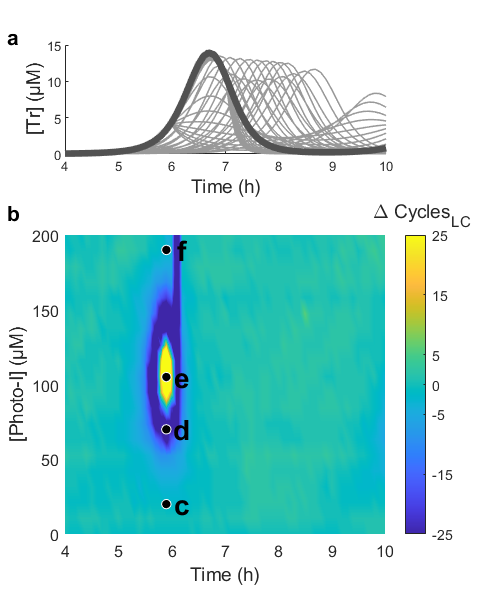

%Parameters for the run
PhotoIPoints=[20 70 105 190]*1e-3;
FigureLetters={'c','d','e','f'};

figure('DefaultAxesFontSize',12)
width=500;
height=600;
set(gcf,'position',[100,100,width,height])

% subfigure a - initial recovery trajectories
c1=subplot(8,1,1:2);
hold on
PhotoIArray2=linspace(200,0,10)*1e-3;
Time=20;
IrrTimeStartArray2=[4.0 5.0 6.0 7.0 8.0 9.0 10.0];

for IrrTimeStart=IrrTimeStartArray2
    for PhotoInh=PhotoIArray2
        [t2,y2]=OscIntegration(volume,flowrate, R_1,Tg0,Tr0,ProI0,Ap0, PhotoInh,Time,  IrrTimeStart, IrrDuration0);
        Tr2=y2(:,2)*1000;
        Inh2=y2(:,5)*1000;
        [pks2,locs2] = findpeaks(Tr2,'MinPeakHeight',1);
        
        if PhotoInh==0
            plot(t2(t2<10.1 & t2>0),Tr2(t2<10.1 & t2>0),'LineWidth',5,"Color",Color_Osc);
        else
            plot(t2,Tr2,'LineWidth',1,"Color",Color_OscGrey);
        end
        xlim([4 10])
        xlabel('Time (h)','FontSize',14);
        ylabel('[Tr] (µM)','FontSize',14);
    end
end
hold off

text(-0.18, 1.2 ,'a','Units','normalized','HorizontalAlignment', 'left', 'VerticalAlignment','top','FontSize',16,"FontWeight","bold");
% Add an empty colorbar, so both subfigures are nicely aligned
c=colorbar;
c.Color='white';
colormap(c1,[]);
box off;

% subfigure b - Heatmap
s2=subplot(8,1,4:8);
hold on
IrrTimeStart=5.9;
h=pcolor(IrrTimeStartArray,PhotoIArray*1e3,DeltaCycles);
scatter(IrrTimeStart*ones(size(PhotoIPoints)),PhotoIPoints*1e3,50,'k',"filled",'MarkerEdgeColor','w','LineWidth',0.5)

text(IrrTimeStart*ones(size(PhotoIPoints))*1.05,PhotoIPoints*1e3,FigureLetters,'HorizontalAlignment', 'center', 'VerticalAlignment','middle','FontSize',21,"FontWeight","bold")
text(-0.18, 1.12 ,'b','Units','normalized','HorizontalAlignment', 'left', 'VerticalAlignment','top','FontSize',16,"FontWeight","bold");
set(h, 'EdgeColor', 'none');
xticks(4:1:10)
xlabel('Time (h)','FontSize',14);
ylabel('[Photo-I] (µM)','FontSize',14);

caxis([-25 25])
c=colorbar;
c.Ticks=sort([linspace(-25,25,6) 0]);

if isfile('brewermap.m')
    cmap= brewermap([5],'PRGn');
    colormap(s2,cmap);
end

shading interp;
c.Label.String = '\Delta Cycles_L_C';
c.Label.FontSize = 14;
c.Label.Rotation = 0;
pos = get(c,'Position');
c.Label.Position = [pos(1) 31];

## Figure 3c-f

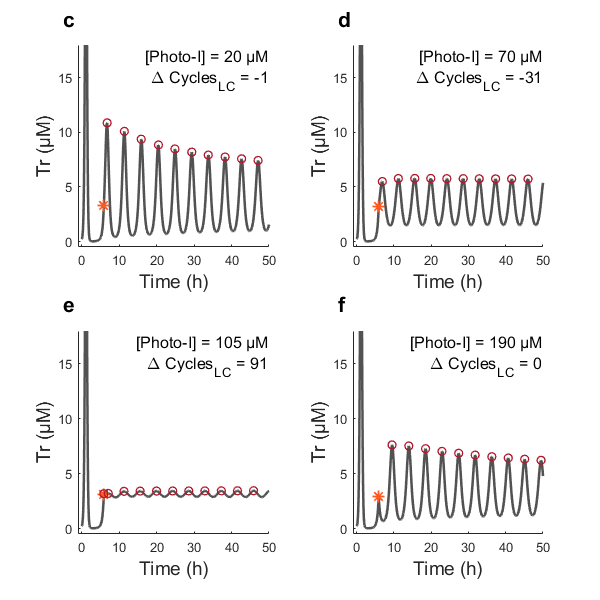

figure
width=600;
height=600;
set(gcf,'position',[10,10,width,height],'DefaultAxesFontSize',14)
tiles = tiledlayout(2,2,'TileSpacing','normal','Padding', 'normal');
R_1=1;
for i=1:length(PhotoIPoints)
    PhotoInh=PhotoIPoints(i);
    
    [~,y]=OscIntegration(volume,flowrate, R_1,Tg0,Tr0,ProI0,Ap0, PhotoInh,1000,  999, IrrDuration0);
    Tr=y(:,2)*1000;
    [CyclesNoPert,TrMax_LC]=FindLC(Tr, 0.4,[]);
    
    [t,y]=OscIntegration(volume,flowrate, R_1,Tg0,Tr0,ProI0,Ap0, PhotoInh,1000,  IrrTimeStart, IrrDuration0);
    Tr=y(:,2)*1000;
    [CyclesPert,~]=FindLC(Tr, 0.4,TrMax_LC);
    
    DeltaCycles=CyclesPert-CyclesNoPert;
    [pks,locs] = findpeaks((Tr),'MinPeakHeight',3);
    
    nexttile
    hold on
    
    plot(t,Tr,'-','LineWidth',2, 'Color', Color_Osc);
    scatter(t(t==IrrTimeStart), Tr(t==IrrTimeStart),80,[255 87 31]/255,'*','LineWidth',1.3)
    plot(t(locs),pks,'o', 'LineWidth',1, 'Color', Color_Tops)
    
    text(-0.08, 1.2 ,FigureLetters(i),'Units','normalized','HorizontalAlignment', 'left', 'VerticalAlignment','top','FontSize',16,"FontWeight","bold");
    text(1, 1 ,['[Photo-I] = ' num2str(PhotoInh*1e3,'%.0f') ' µM' newline '\Delta Cycles_L_C = ' num2str(DeltaCycles,'%.0f') ],'Units','normalized','HorizontalAlignment', 'right', 'VerticalAlignment','top','FontSize',12);
    xlim([-1 50]);
    ylim([-0.5 18]);
    xlabel('Time (h)','FontSize',14);
    ylabel('Tr (µM)','FontSize',14);
end

## Limit cycle

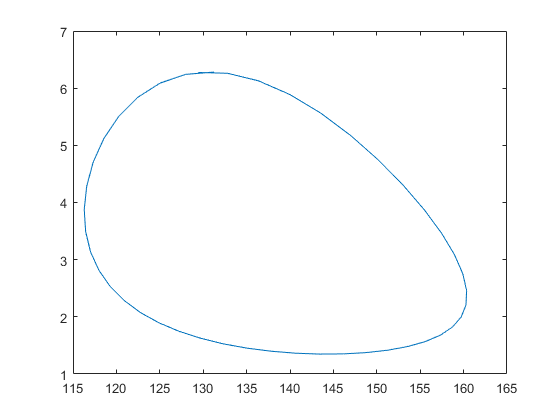

%Parameters different from the default parameters
PhotoInh=0;
IrrTimeStart=5.9;

%% Limit cycle
[~,y]=OscIntegration(volume,flowrate, R_1,Tg0,Tr0,ProI0,Ap0, PhotoInh,1000, IrrTimeStart, 2);
Tr=y(:,2)*1000;
[pks,locs] = findpeaks(Tr,'MinPeakHeight',1);
y_LC=y(locs(end-2):locs(end-1),:);
Inh_LC=y_LC(:,5)*1000;
Tr_LC=y_LC(:,2)*1000;
figure
plot(Inh_LC,Tr_LC);

TrMax_LC=pks(end); %Value of [Tr]max in the limit cycle

## Figure 4

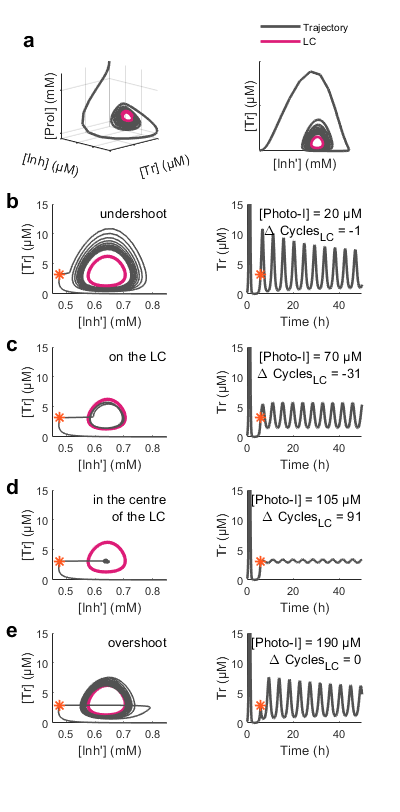

%Parameters different from the default parameters
PhotoInh=0;
IrrTimeStart=5.9;

[~,y]=OscIntegration(volume,flowrate, R_1,Tg0,Tr0,ProI0,Ap0, PhotoInh,50,  IrrTimeStart, IrrDuration0);
Tr=y(:,2)*1000;
Inh=y(:,5)*1000;
Pro=y(:,3);

figure
width=400;
height=812;
set(gcf,'position',[10,10,width,height])
tiles = tiledlayout(5,2,'TileSpacing','normal','Padding', 'normal');

nexttile
hold on
plot3(Tr,Inh,Pro,'LineWidth',2, 'Color', Color_Osc)
plot3(Tr_LC,Inh_LC,y_LC(:,3),'Color',Color_LC,'LineWidth',3)

grid on
hAxis=gca;
pbaspect([1 1 1])
ylabel('[Inh] (µM)','FontSize',10, 'Rotation',-15);
xlabel('[Tr] (µM)','FontSize',10,'Rotation',15);
zlabel('[ProI] (mM)','FontSize',10);
set(gca,'XTickLabel',[],'YTickLabel',[],'ZTickLabel',[]);
view(135,15)
text(-0.4, 1.4 ,'a','Units','normalized','HorizontalAlignment', 'left', 'VerticalAlignment','top','FontSize',16,"FontWeight","bold");

nexttile()
hold on

[Tr_proj,Inh_proj]=Projection(Tr,Inh,Pro,180,30);
plot(Inh_proj-min(Inh_proj),Tr_proj*max(Tr),'LineWidth',2, 'Color', Color_Osc)
[Tr_LC_proj,Inh_LC_proj]=Projection([Tr_LC; max(Tr)],[Inh_LC; max(Inh)],[y_LC(:,3); max(Pro)] ,180,30);
Tr_LC_proj=Tr_LC_proj(1:end-1)*max(Tr);
Inh_LC_proj=Inh_LC_proj(1:end-1)-min(Inh_proj);
plot(Inh_LC_proj,Tr_LC_proj,'LineWidth',2, 'Color', Color_LC)

axis square
xlabel('[Inh''] (mM)' ,'FontSize',10);
ylabel('[Tr] (µM)','FontSize',10);
set(gca,'XTickLabel',[],'YTickLabel',[]);
legend('Trajectory','LC','location','northoutside')
legend('boxoff')


PhotoIArray3=[20 70 105 190]*1e-3;
FigureLetters={'b','c','d','e'};
FigureText={'undershoot', 'on the LC',['in the centre' newline 'of the LC'],'overshoot'};
for i=1:length(PhotoIArray3)
    PhotoInh=PhotoIArray3(i);
    nexttile
    hold on
    [~,y]=OscIntegration(volume,flowrate, R_1,Tg0,Tr0,ProI0,Ap0, PhotoInh,1000,  999, IrrDuration0);
    Tr1=y(:,2)*1000;
    [CyclesPert,TrMax_LC]=FindLC(Tr1, 0.4,[]);
    
    [t,y]=OscIntegration(volume,flowrate, R_1,Tg0,Tr0,ProI0,Ap0, PhotoInh,1000,  IrrTimeStart, IrrDuration0);
    Tr=y(:,2)*1000;
    Inh=y(:,5)*1000;
    Pro=y(:,3);
    
    [CyclesNoPert,~]=FindLC(Tr, 0.4,TrMax_LC);
    NumberOrbits=CyclesNoPert-CyclesPert;
    [Tr_proj,Inh_proj]=Projection(Tr,Inh,Pro,180,30);
    Tr_proj=Tr_proj*max(Tr);
    Inh_proj=Inh_proj-min(Inh_proj);
    
    plot(Inh_LC_proj,Tr_LC_proj,'LineWidth',2.5, 'Color', Color_LC)
    plot(Inh_proj(t<50),Tr_proj(t<50),'LineWidth',1,'LineStyle',"-",'Color', Color_Osc)
    
    scatter(Inh_proj(t==IrrTimeStart), Tr_proj(t==IrrTimeStart),70,Color_Orange,'*','LineWidth',1.3)
    xlabel('[Inh''] (mM)' ,'FontSize',10);
    ylabel('[Tr] (µM)','FontSize',10);
    ylim([0 15])
    xlim([0.45 0.85])
    text(-0.4, 1.2 ,FigureLetters(i),'Units','normalized','HorizontalAlignment', 'left', 'VerticalAlignment','top','FontSize',16,"FontWeight","bold");
    text(1.0, 1.0 ,FigureText(i),'Units','normalized','HorizontalAlignment', 'right', 'VerticalAlignment','top');
    
    nexttile
    hold on
    plot(t,Tr,'LineWidth',2, 'Color', Color_Osc);
    xlabel('Time (h)','FontSize',10);
    ylabel('Tr (µM)','FontSize',10);
    scatter(t(t==IrrTimeStart), Tr(t==IrrTimeStart),70,Color_Orange,'*','LineWidth',1.3)
    text(1, 1 ,['[Photo-I] = ' num2str(PhotoInh*1e3,'%.0f') ' µM' newline '\Delta Cycles_L_C = ' num2str(NumberOrbits,'%.0f')],'Units','normalized','HorizontalAlignment', 'right', 'VerticalAlignment','top');
    xlim([0 50])
    ylim([0 15])
end

## Figure 5b-d 

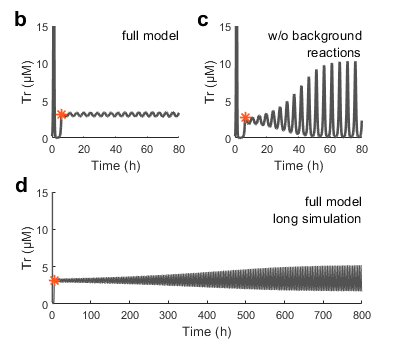

% Parameters for the figure
PhotoInh=105*1e-3;
IrrTimeStart=5.9;

figure
width=400;
height=350;
set(gcf,'position',[10,10,width,height])
tiles = tiledlayout(2,2,'TileSpacing','normal','Padding', 'normal');

nexttile
hold on
[t,y]=OscIntegration(volume,flowrate, 1,Tg0,Tr0,ProI0,Ap0, PhotoInh,1000,  IrrTimeStart, IrrDuration0);
Tr=y(:,2)*1000;
Inh=y(:,5)*1000;
plot(t,Tr,'LineWidth',2, 'Color', Color_Osc)
scatter(t(t==IrrTimeStart), Tr(t==IrrTimeStart),70,Color_Orange,'*','LineWidth',1.3)

text(1, 1 ,['full model'],'Units','normalized','HorizontalAlignment', 'right', 'VerticalAlignment','top');
text(-0.3, 1.2 ,'b','Units','normalized','HorizontalAlignment', 'left', 'VerticalAlignment','top','FontSize',16,"FontWeight","bold");
xlim([0 80])
ylim([0 15])
xlabel('Time (h)','FontSize',10);
ylabel('Tr (µM)','FontSize',10);

nexttile
hold on
IrrTimeStart2=6.3;
[t,y]=OscIntegration(volume,flowrate, {'all side react off'},Tg0,Tr0,ProI0,Ap0, PhotoInh,80,  IrrTimeStart2, IrrDuration0);
Tr=y(:,2)*1000;
plot(t,Tr,'LineWidth',2, 'Color', Color_Osc)
scatter(t(t==IrrTimeStart2), Tr(t==IrrTimeStart2),70,Color_Orange,'*','LineWidth',1.3)

text(1, 1 ,[{'w/o background','reactions'}],'Units','normalized','HorizontalAlignment', 'right', 'VerticalAlignment','top');
text(-0.3, 1.2 ,'c','Units','normalized','HorizontalAlignment', 'left', 'VerticalAlignment','top','FontSize',16,"FontWeight","bold");
xlim([0 80])
ylim([0 15])
xlabel('Time (h)','FontSize',10);
ylabel('Tr (µM)','FontSize',10);

nexttile([1 2])
hold on
[t,y]=OscIntegration(volume,flowrate, 1,Tg0,Tr0,ProI0,Ap0, PhotoInh,800,  IrrTimeStart, IrrDuration0);
Tr=y(:,2)*1000;
Inh=y(:,5)*1000;
plot(t,Tr,'LineWidth',0.2, 'Color', Color_Osc)
scatter(t(t==IrrTimeStart), Tr(t==IrrTimeStart),70,Color_Orange,'*','LineWidth',1.3)

text(1, 1 ,[{'full model','long simulation'} ],'Units','normalized','HorizontalAlignment', 'right', 'VerticalAlignment','top');
text(-0.12, 1.2 ,'d','Units','normalized','HorizontalAlignment', 'left', 'VerticalAlignment','top','FontSize',16,"FontWeight","bold");
% xlim([0 50])
ylim([0 15])
xlabel('Time (h)','FontSize',10);
ylabel('Tr (µM)','FontSize',10);

## Supplementary information Figure

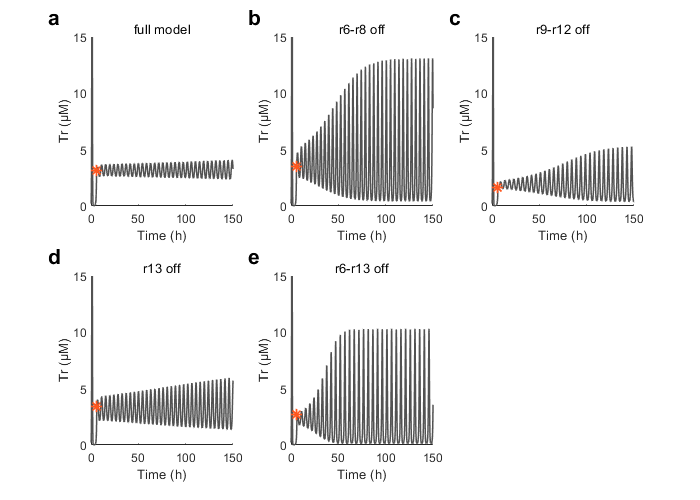

% Parameters for the figure
PhotoInh=100*1e-3;
IrrTimeStart=5.9;
R1_array={'full',  'back inh off','hydrolysis off','Tg autolysis off','all side react off'};
IrrTimeArray3=[5.9 5.8 6.3 6.1 6.3];
FigureText_array={'full model',  ['r6-r8 off'],['r9-r12 off'],['r13 off'],['r6-r13 off']};
FigureLetter_array={'a','b','c','d','e'};

figure
width=700;
height=500;
set(gcf,'position',[10,10,width,height])

tiles = tiledlayout(2,3,'TileSpacing','normal','Padding', 'normal');

for j=1:length(R1_array)
    R_1=R1_array(j);
    IrrTimeStart=IrrTimeArray3(j);
    FigureText=FigureText_array(j);
    FigureLetter=FigureLetter_array(j);
    
    nexttile
    hold on
    
    [t,y]=OscIntegration(volume,flowrate, R_1,Tg0,Tr0,ProI0,Ap0, PhotoInh,1000,  IrrTimeStart, IrrDuration0);
    Tr=y(:,2)*1000;
    Inh=y(:,5)*1000;
    [pks,locs] = findpeaks(Tr,'MinPeakHeight',1);
    TrMax_LC2=pks(end);
    peaks_LC=abs(pks-TrMax_LC2)<0.3;
    NumberOrbits=find(peaks_LC,1);
    
    plot(t,Tr,'LineWidth',1, 'Color', Color_Osc)
    scatter(t(t==IrrTimeStart), Tr(t==IrrTimeStart),70,Color_Orange,'*','LineWidth',1.3)
    
    text(0.5, 1.1 ,FigureText,'Units','normalized','HorizontalAlignment', 'center', 'VerticalAlignment','top');
    text(-0.3, 1.2 ,FigureLetter,'Units','normalized','HorizontalAlignment', 'left', 'VerticalAlignment','top','FontSize',16,"FontWeight","bold");
    xlim([0 150])
    ylim([0 15])
    xlabel('Time (h)','FontSize',10);
    ylabel('Tr (µM)','FontSize',10);
end

## Calculation of average reaction rates during oscillations (core reactions vs side reactions.

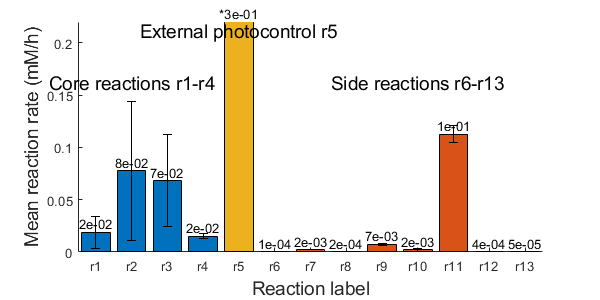

%Parameters
PhotoInh=50*1e-3; 
Time=300;
IrrTimeStart=299; 
IrrDuration=0.08;

%Integration
[t,y]=OscIntegration(volume,flowrate, 'full',Tg0,Tr0,ProI0,Ap0, PhotoInh,Time,  IrrTimeStart, IrrDuration);

%Calculate mean concentrations and standard devation of concentrations during oscillations
mean_y=median(y);
std_y=std(y);

%Calculate mean reaction rates
mean_rate(1)=mean_y(6)*35.77;
mean_rate(2)=mean_y(7)*1027;
mean_rate(3)=4.495*mean_y(4)/(mean_y(4)+2.39);
mean_rate(4)=mean_y(2)*mean_y(5)*42.7;
mean_rate(5)=mean_y(14)*100;
mean_rate(6)=mean_y(2)*mean_y(4)*1.46;
mean_rate(7)=mean_y(2)*mean_y(3)*1.34;
mean_rate(8)=mean_y(2)*mean_y(14)*1.40;
mean_rate(9)=mean_y(5)*0.054;
mean_rate(10)=mean_y(4)*0.055;
mean_rate(11)=mean_y(3)*0.176;
mean_rate(12)=mean_y(14)*0.0075;
mean_rate(13)=mean_y(1)*mean_y(1)*0.0044;

%Calculate standard deviation of reaction rates
mean_rate_std(1)=std_y(6)*35.77;
mean_rate_std(2)=std_y(7)*1027;
mean_rate_std(3)=4.495*std_y(4)/(std_y(4)+2.39);
mean_rate_std(4)=std_y(2)*std_y(5)*42.7;
mean_rate(5)=std_y(14)*100;
mean_rate_std(6)=std_y(2)*std_y(4)*1.46;
mean_rate_std(7)=std_y(2)*std_y(3)*1.34;
mean_rate_std(8)=std_y(2)*std_y(14)*1.40;
mean_rate_std(9)=std_y(5)*0.054;
mean_rate_std(10)=std_y(4)*0.055;
mean_rate_std(11)=std_y(3)*0.176;
mean_rate_std(12)=std_y(14)*0.0075;
mean_rate_std(13)=std_y(1)*std_y(1)*0.0044;

%Plotting
figure
width=600;
height=300;
set(gcf,'position',[10,10,width,height])
x_labels = categorical({'r1','r2','r3','r4','r5', 'r6', 'r7', 'r8', 'r9', 'r10', 'r11', 'r12', 'r13'});
x_labels = reordercats(x_labels ,{'r1','r2','r3','r4','r5', 'r6', 'r7', 'r8', 'r9', 'r10', 'r11', 'r12', 'r13'});

hold on
bar(x_labels(1:4),mean_rate(1:4));
bar(x_labels(6:end),mean_rate(6:end));
bar(x_labels(5),mean_rate(5));
ylim([0, 0.22])


er = errorbar(mean_rate, mean_rate_std);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

text(1:length(mean_rate),mean_rate,num2str(mean_rate','%0.0e'),'vert','bottom','horiz','center'); 
text(5,0.22,['*', num2str(mean_rate(5)','%0.0e')],'vert','bottom','horiz','center'); 

xlabel('Reaction label','FontSize',14);
ylabel('Mean reaction rate (mM/h)','FontSize',14);

text(2,0.15,'Core reactions r1-r4','vert','bottom','horiz','center','FontSize',14); 
text(10,0.15,'Side reactions r6-r13','vert','bottom','horiz','center','FontSize',14); 
text(5,0.2,'External photocontrol r5','vert','bottom','horiz','center','FontSize',14); 

function [NumberCycles, TrMax_LC]=FindLC(Tr, Distance, TrMax_LC) % Function that calculates the number of cycles to get to the limit cycle
[pks,~] = findpeaks(Tr,'MinPeakHeight',3);

    if isempty(TrMax_LC)
        TrMax_LC=pks(end-2);
    end

peaks_LC=abs(pks-TrMax_LC)<Distance;
NumberCycles=find(peaks_LC,1);

    if isempty(NumberCycles)
        NumberCycles=200;
    end

end

% Function that performs an orthographic projection of a 3D limit cycle to
% a 2D limit cycle. For more info see:
% https://nl.mathworks.com/matlabcentral/answers/248362-screen-2d-projection-of-3d-plot
% https://blogs.mathworks.com/graphics/2015/09/28/homogeneous-coordinates/
function [x_proj,y_proj]=Projection(x,y,z,al,el)
pts = [x'; y'; z'; ones(size(x'))];
T = viewmtx(al, el)* makehgtform('scale',1./[max(x) max(y) max(z)]);
projection =T * pts;
x_proj = -projection(1,:) ./ projection(4,:);
y_proj = (-projection(2,:) ./ projection(4,:)); %+max(pt2(2,:))
end


function [t,y]=OscIntegration(Volume,flowrate,  R_1,Tg,Tr,ProI,Ap, NVOC_I,Time, IrrTimeStart, IrrDuration)
kflow       = flowrate/Volume; % in 1/h
% Optimized rate constants. See [Semenov, Wong, et al; Nature Chemistry 2015] S4.3.2 Table S3
%https://doi.org/10.1038/nchem.2142

k.kf_auto_tr    =	73.55;
k.kr_auto_tr    =	1.60;
k.kc_auto_tr    =	35.77;
k.kc_delay      =	0.145;
k.Km_delay      =	2.39;
k.kf_inh_i      =	42.68;
k.kf_inh_ai     = 1.458;
k.kf_degr_i     =	0.0542;
k.kf_degr_ai 	=   0.0547;
k.kc_auto_tg	=   0.00442;
k.kflow         =   kflow;
k.Km_act        =	21.9;
k.kf_act        =	614.27;
k.kc_act        =	1027;
k.kr_act        =	k.Km_act*k.kf_act-k.kc_act;

% Rate constants for a full model or several truncated models.
if isa(R_1,'double')
    R_1={'full'};
end
if strcmp(R_1,'full') 
    k.kf_inh_aai    =	1.34;
    k.kf_degr_aai	=   0.176;
    k.kf_degr_photoi=0.0075;
    k.kf_inh_photoi=1.40;
        
elseif strcmp(R_1,'all side react off') %special case where there are now hydrolysis reactions going on
    k.kf_inh_aai    =	0;
    k.kf_degr_aai	=   0;
    k.kf_degr_photoi=0;
    k.kf_inh_photoi=0;
    k.kf_inh_ai     = 0;
    k.kf_degr_i     =	0;
    k.kf_degr_ai 	=   0;
    
elseif strcmp(R_1,'back inh off') % Background inh is off (r6-r8 is off)
    k.kf_inh_aai    =	0;
    k.kf_degr_aai	=   0.176;
    k.kf_degr_photoi=0.0075;
    k.kf_inh_photoi=0;
    k.kf_inh_ai     = 0;
    k.kf_degr_i     =	0.0542;
    k.kf_degr_ai 	=   0.0547;
    
elseif strcmp(R_1,'hydrolysis off') % Hydrolysis is off (r9-12 off)
    k.kf_inh_aai    =	1.34;
    k.kf_degr_aai	=   0;
    k.kf_degr_photoi=0;
    k.kf_inh_photoi=1.4;
    k.kf_inh_ai     = 1.458;
    k.kf_degr_i     =	0;
    k.kf_degr_ai 	=   0;
        
elseif strcmp(R_1,'Tg autolysis off')
    k.kf_inh_aai    =	1.34;
    k.kf_degr_aai	=   0.176;
    k.kf_degr_photoi=0.0075;
    k.kf_inh_photoi=1.4;
    k.kc_auto_tg	=   0;   
end

xo      = zeros(1,16);
xo(1) = Tg;
xo(2) = Tr;
xo(3) = ProI;
Apep  = Ap;
k.Vmax_delay=k.kc_delay*Apep;
xo(14)  = NVOC_I;

%% NUMERICAL INTEGRATION BASED ON IRREVERSIBLE INHIBITION (alex):
OPTIONS             = ['AbsTol',1e-4,'NonNegative',1, 'MaxStep',0.1];
t = [];
y = [];
inflow_cond=xo;  %condtions in the time of starting reactor

%  1st run - before the irradiation
TimeStepLong=0.1;
k.photo_cleav   =   0.00; % no irradiation
[t1,y1] = ode23tb(@ODE_TrypsinOsc, [0:TimeStepLong:IrrTimeStart], xo, OPTIONS , k, kflow, inflow_cond);
yo_1      = y1(end,1:16);

% 2st run  - during the irradiation
k.photo_cleav   =  100; % irradiation turned on 
saved.k.photo_cleav = k.photo_cleav;
TimeStep=0.01;
[t2,y2] = ode23tb(@ODE_TrypsinOsc, [IrrTimeStart:TimeStep:IrrTimeStart+IrrDuration], yo_1, OPTIONS , k, kflow, inflow_cond);
yo_2      = y2(end,1:16);


% 3rd run -after the irradiation
k.photo_cleav   =   0; % irradiation turned off
[t3,y3] = ode23tb(@ODE_TrypsinOsc, [IrrTimeStart+IrrDuration:TimeStepLong:Time], yo_2, OPTIONS , k, kflow, inflow_cond);

%   Summary
t=[t1(1:end-1); t2(1:end-1); t3(1:end-1)];
y=cat(1, y1(1:end-1,:), y2(1:end-1,:), y3(1:end-1,:));

end

%% Ordinary differential equations, that describe the system
function [f] = ODE_TrypsinOsc(~,y,k,kflow,xo)
%% SETTINGS
% Make descriptors and number them for y-vector, so the rate eqns are
% easier on the eye.
dTg      = 1;
dTr      = 2;
daaI     = 3;
daI      = 4;
dI       = 5;
dTr_Tg   = 6;
dTr_aaI  = 7;
daaI_Tr  = 8;
daI_Tr   = 9;
dI_Tr    = 10;
daaIOH   = 11;
daIOH    = 12;
dIOH     = 13;
dNVOC_I     = 14;
dNVOC_IOH     = 15;
dTr_NVOC_I     = 16;

% Species are coupled to y-vector.
Tg       = y(dTg);
Tr       = y(dTr);
aaI      = y(daaI);
aI       = y(daI);
I        = y(dI);
Tr_Tg    = y(dTr_Tg);
Tr_aaI   = y(dTr_aaI);
aaI_Tr   = y(daaI_Tr);
aI_Tr    = y(daI_Tr);
I_Tr     = y(dI_Tr);
aaIOH    = y(daaIOH);
aIOH     = y(daIOH);
IOH      = y(dIOH);
NVOC_I   = y(dNVOC_I);
NVOC_IOH=y(dNVOC_IOH);
Tr_NVOC_I=y(dTr_NVOC_I);

%% RATE EQNS

f(dTg)      = -(k.kf_auto_tr*Tr+k.kc_auto_tg*Tg+kflow)*Tg+k.kr_auto_tr*Tr_Tg+kflow*xo(dTg);
f(dTr)      = -(k.kf_auto_tr*Tg+(k.kf_act+k.kf_inh_aai)*aaI+k.kf_inh_ai*aI+k.kf_inh_photoi*NVOC_I+k.kf_inh_i*I+kflow)*Tr...
    +(k.kr_auto_tr+2*k.kc_auto_tr)*Tr_Tg+(k.kr_act+k.kc_act)*Tr_aaI+k.kc_auto_tg*Tg*Tg+kflow*xo(dTr);
f(daaI)     = -((k.kf_act+k.kf_inh_aai)*Tr+k.kf_degr_aai+kflow)*aaI+k.kr_act*Tr_aaI+kflow*xo(daaI);
f(daI)      = k.kc_act*Tr_aaI-((k.Vmax_delay/(k.Km_delay+aI))+k.kf_inh_ai*Tr+k.kf_degr_ai+kflow)*aI;
f(dI)       = (k.Vmax_delay/(k.Km_delay+aI))*aI-(k.kf_inh_i*Tr+k.kf_degr_i+kflow)*I+k.photo_cleav*NVOC_I;
f(dTr_Tg)   = k.kf_auto_tr*Tg*Tr-(k.kr_auto_tr+k.kc_auto_tr+kflow)*Tr_Tg;
f(dTr_aaI) 	= k.kf_act*Tr*aaI-(k.kr_act+k.kc_act+kflow)*Tr_aaI;

f(daaI_Tr)	= k.kf_inh_aai*aaI*Tr-kflow*aaI_Tr;
f(daI_Tr)   = k.kf_inh_ai*aI*Tr-kflow*aI_Tr;
f(dI_Tr)    = k.kf_inh_i*I*Tr-kflow*I_Tr;
f(daaIOH)   = k.kf_degr_aai*aaI-kflow*aaIOH;
f(daIOH)    = k.kf_degr_ai*aI-kflow*aIOH;
f(dIOH)     = k.kf_degr_i*I-kflow*IOH;

f(dNVOC_I)   = -k.photo_cleav*NVOC_I+kflow*(-NVOC_I+xo(dNVOC_I))-k.kf_degr_photoi*NVOC_I-k.kf_inh_photoi*NVOC_I*Tr;
f(dNVOC_IOH)=+k.kf_degr_photoi*NVOC_I-kflow*NVOC_IOH;
f(dTr_NVOC_I)=+k.kf_inh_photoi*NVOC_I*Tr-kflow*Tr_NVOC_I;
% Turn from row to column vector for solver function to be able to read
% it.
f       = f';
end
